# Приложение

## Настраиваемые параметры

- Количество сравниваемых сигналов (2...6)

- Границы диапазона изменения значений сигналов (-100...100)

- Вид функции принадлежности

### Количество сравниваемых сигналов

## Функции принадлежности и их параметры

### trimf

Ширина ФП:$a = \frac{\left| min(x)\right| + max(x)}{2}$

Количество настраиваемых параметров: 1

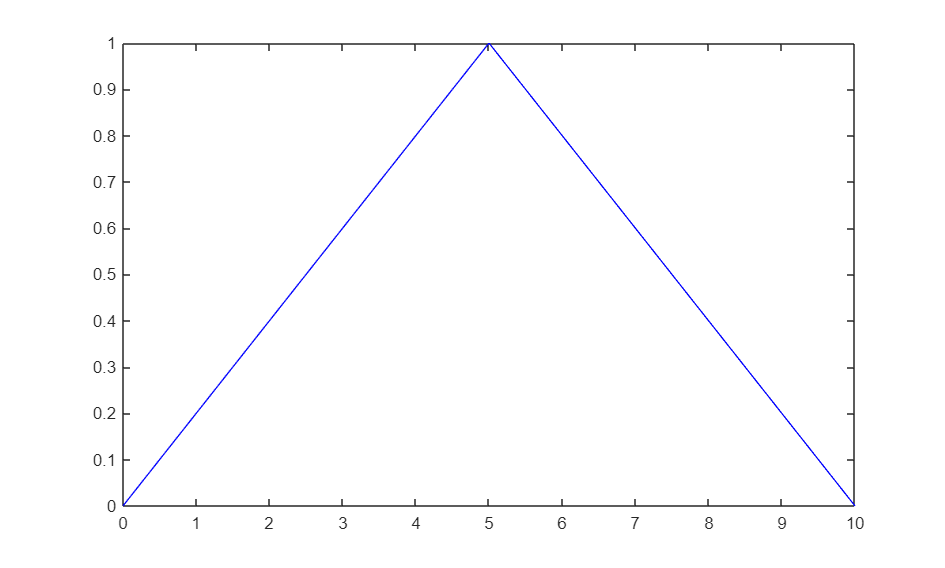

x = 0:0.01:10;
a =5;
x1 =5;
y = trimf(x,[x1-a x1 x1+a]);
figure(Units = "centimeters", Position = [0 0 20 12])
plot(x, y, Color = 'b');
axis([0 10 0 1])
xticks(0:1:10)

### gaussmf

Ширина ФП:$a = \frac{\left| min(x)\right| + max(x)}{2}$

Количество настраиваемых параметров: 1

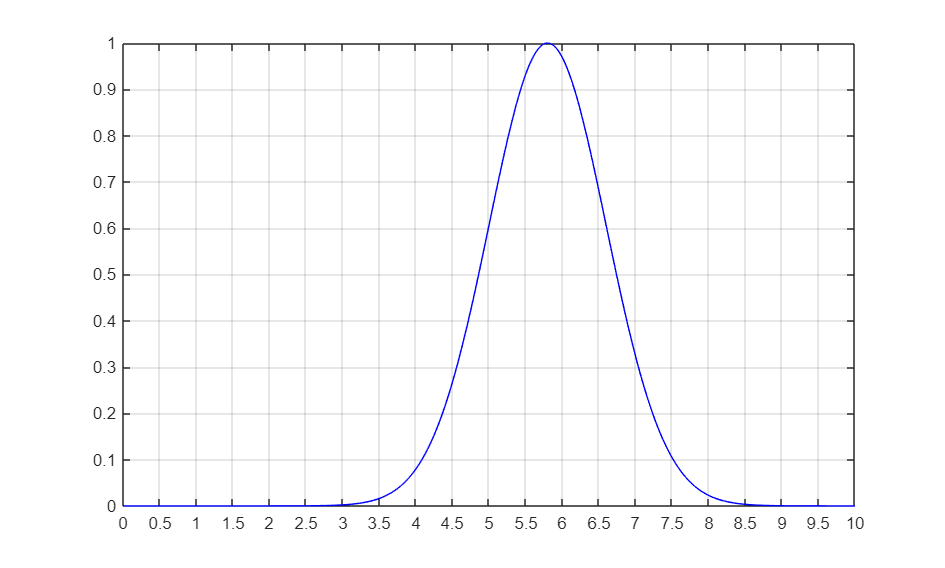

x = 0:0.01:10;
a =0.8;
x1 =5.8;
y = gaussmf(x,[a x1]);
figure(Units = "centimeters", Position = [0 0 20 12])
plot(x, y, Color = 'b');
axis([0 10 0 1])
xticks(0:0.5:10)
grid on

### `gbellmf`

Ширина ФП:$a = \frac{\left| min(x)\right| + max(x)}{2}$

Количество настраиваемых параметров: 2

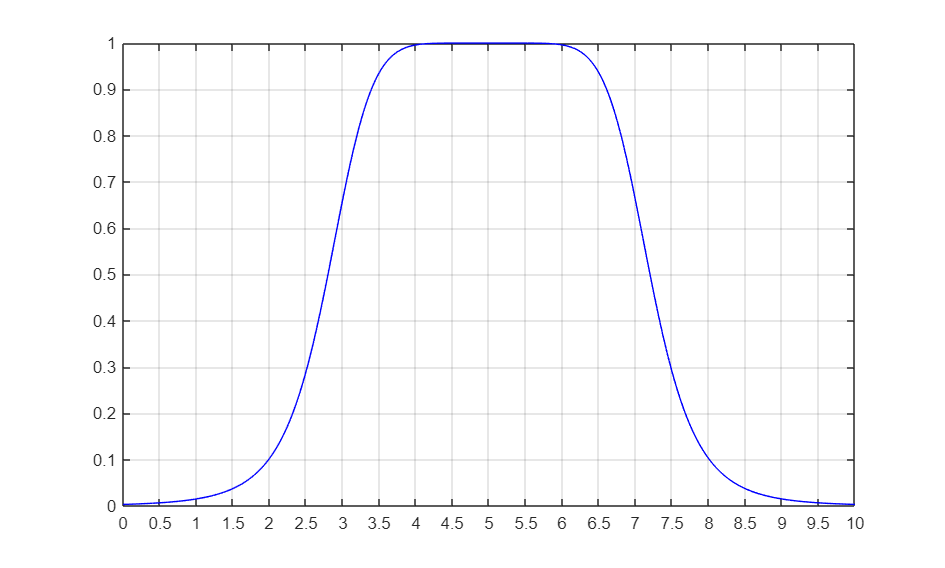

x = 0:0.01:10;
a =2.2;
b1 =3.5;
x1 =5;
y = gbellmf(x,[a b1 x1]);
figure(Units = "centimeters", Position = [0 0 20 12])
plot(x, y, Color = 'b');
axis([0 10 0 1])
xticks(0:0.5:10)
grid on

### `dsigmf`

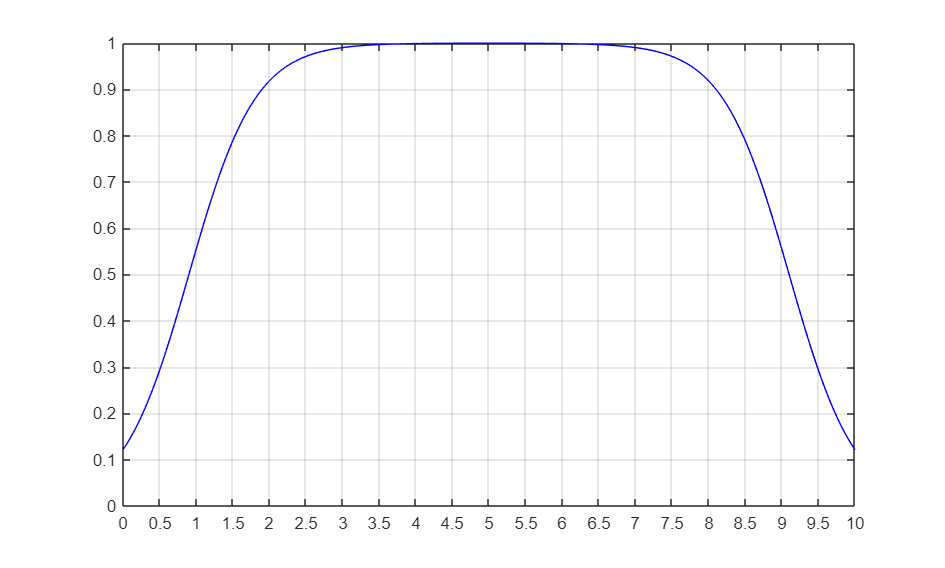

x = 0:0.01:10;
a =2.2;
c1 =4.1;
x1 =5;
y = dsigmf(x,[a x1-c1 a x1+c1]);
figure(Units = "centimeters", Position = [0 0 20 12])
plot(x, y, Color = 'b');
axis([0 10 0 1])
xticks(0:0.5:10)
grid on

### pimf

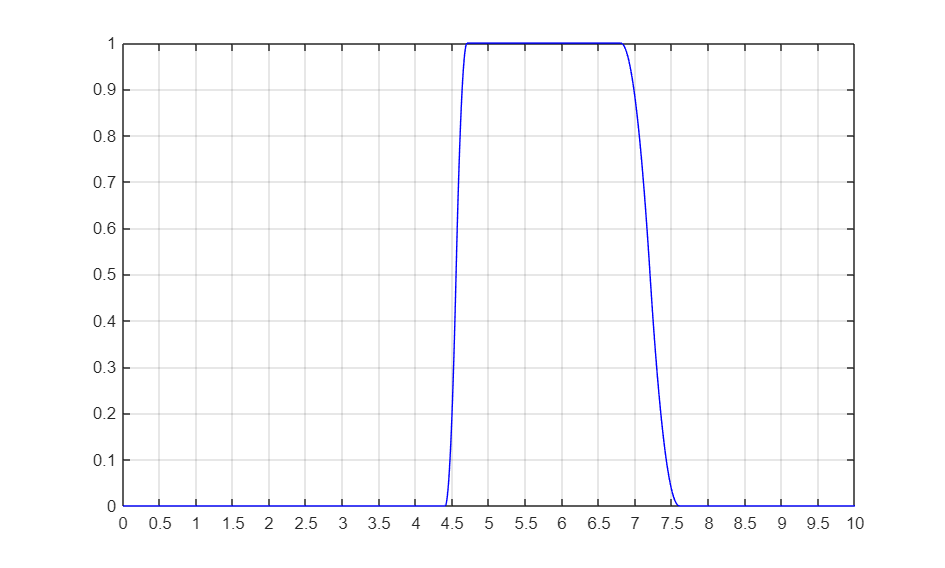

x = 0:0.01:10;
a =1.6;
b1 =1.3;
b2 =0.8;
x1 =6;
y = pimf(x,[x1-a x1-b1 x1+b2 x1+a]);
figure(Units = "centimeters", Position = [0 0 20 12])
plot(x, y, Color = 'b');
axis([0 10 0 1])
xticks(0:0.5:10)
grid on

### trapmf

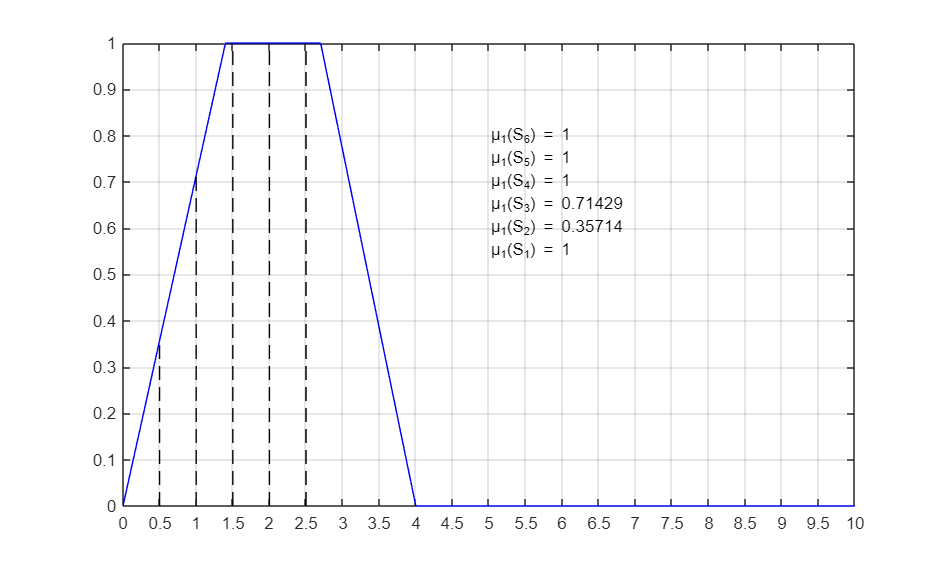

x = 0:0.01:10;
a =2;
b1 =0.6;
b2 =0.7;
x1 =2;
X = 4.5;
y = trapmf(x,[x1-a x1-b1 x1+b2 x1+a]);
% MF1 = trapmf(X, [x1-a x1-b1 x1+b2 x1+a]);
TrustMatrix = zeros(6,6);
Signals = [2 0.5 1 1.5 2 2.5];
for i = 1:6
            for j = 1:6
                TrustMatrix(j,i) = trapmf(Signals(j), [Signals(i)-a Signals(i)-b1 Signals(i)+b2 Signals(i)+a]);
            end
end

% figure(Units = "centimeters", Position = [0 0 20 12])
cla
plot(x, y, Color = 'b');
hold on
for k = 1:6
    line([Signals(k) Signals(k)], [0 TrustMatrix(k,1)], Color = 'k', LineStyle = '--');
    text(5,0.5+k/20, ['\mu_{1}(S_' num2str(k) ') = ' num2str(TrustMatrix(k,1))])
end
axis([0 10 0 1])
xticks(0:0.5:10)
grid on

## Матрица показателей доверия

M(1,:) = arrayfun(@(x) trimf(x, [x1-c x1 x1+c]), a), a = [x1...x6]

M(2,:) = arrayfun(@(x) trimf(x, [x2-c x2 x2+c]), a), a = [x1...x6]

M = eye(6);
for i = 1:6
    for j = 1:6
        M(j,i) = trimf(a(j), [a(i)-2 a(i) a(i)+2]);
    end
end

Index exceeds the number of array elements. Index must not exceed 1.

m = [1 2 3; 4 5 6; 7 8 9];
m = m.*~eye(size(m))
ma = max(m,[],2)
s = sum(ma)
w = ma./s
S = sum(w'.*[3 6 2])

m = [1 2 3; 4 5 6; 7 8 9]
m(1:3,1:3)

## Линии

x = 0:0.01:10;
a =3.4;
x1 =5;
x2 =7;
x3 = 7.4;
yc1 = trimf(x,[x1-a x1 x1+a]);
yc2 = trimf(x,[x2-a x2 x2+a]);
yc3 = trimf(x,[x3-a x3 x3+a]);
muMatrix(1,2) = trimf(x2,[x1-a x1 x1+a]);
muMatrix(1,3) = trimf(x3,[x1-a x1 x1+a]);
muMatrix(2,1) = trimf(x1,[x2-a x2 x2+a]);
muMatrix(2,3) = trimf(x3,[x2-a x2 x2+a]);
muMatrix(3,1) = trimf(x1,[x3-a x3 x3+a]);
muMatrix(3,2) = trimf(x2,[x3-a x3 x3+a]);
mu1Max = max(muMatrix(2,1), muMatrix(3,1));
mu2Max = max(muMatrix(1,2), muMatrix(3,2));
mu3Max = max(muMatrix(1,3), muMatrix(2,3));
muSum = mu1Max + mu2Max + mu3Max;
weight = [mu1Max mu2Max mu3Max]./muSum;
xc = mu1Max*x1/muSum + mu2Max*x2/muSum + mu3Max*x3/muSum; 

xArray = [x1 x2 x3];

figure(Units = "centimeters", Position = [0 0 20 12])
plot(x, yc1, Color = 'b');
hold on

for i = 1:3
    line([xArray(i) xArray(i)],[0 muMatrix(1,i)], LineStyle="--", Color = 'k');
    line([0 xArray(i)], [muMatrix(1,i) muMatrix(1,i)], LineStyle="--", Color = 'k');
end
axis([0 10 0 1])
xticks(0:1:10)

a = [1 0.3 0.4 0.5 0.6];
b = a(find(a ~= 1))

a = magic(3)
for i = 1:3
    find(a == a(i))
end

xline([1 2 3])
hold on
text([1 2 3], [0.1 0.1 0.1], {'x1', 'x2', 'x3'})

b = [1 2 3 1];
length(find(b == 1)) == 1

## Лэйблы

cla
x = 0:pi/64:2*pi;
y = sin(x);
plot(x,y);
hold on
text(gca, 2, 0, 'x_1')

A = [5 5 7 7 7 9];
[a,b] = IndexOfMultiples(A)

a =      1     2     3     4     5


b =      5     7


Groups = cell(1,length(b));
G = cell(1,length(b));
GroupFirstIdx = zeros(1,length(b));
GroupOtherIdx = cell(1,length(b));
for i = 1:length(b)
    G{i} = find(A == b(i));
    GroupFirstIdx(i) = G{i}(1);
    GroupOtherIdx{i} = G{i}(2:end);
    Groups{i} = strjoin(['x_' strjoin(string(find(A == b(i))), ',_')], '');
end
G

G = 1×2 cell array
    {[1 2]}    {[3 4 5]}

Groups

Groups = 1×2 cell array
    {["x_1,_2"]}    {["x_3,_4,_5"]}

x = 0:pi/64:2*pi;
y = sin(x);

figure
cla

subplot(4,1,1)
plot(x,y)

subplot(4,1,2)
plot(x,y)

subplot(4,1,3)
plot(x,y)

subplot(4,1,4)
plot(x,y)

function [Ind,B] = IndexOfMultiples(A)
T   = true(size(A));
off = false;
A   = A(:);
for iA = 1:numel(A)
  if T(iA)          % if not switched already
    d = (A(iA) == A);
    if sum(d) > 1   % More than 1 occurrence found
       T(d) = off;  % switch all occurrences
    end
  end
end
Ind = find(~T);
B = unique(A(~T)');
end